#### Load functions

% this file should be in the same directory as the /functions dir
% restoredefaultpath;
path = '~/Documents/Courses/ELEC-E5620 Audio Signal Processing/Demo_FVN';
addpath([path '/matlab/functions']);

green = 0.3;

### VN Generator

clear all;

N = 8100;   % sequence length
f = 183;     % frequency (pulse density) in Hz
Fs = 48000;
Y = velvet(N, f, 48000);

#### Plot VN

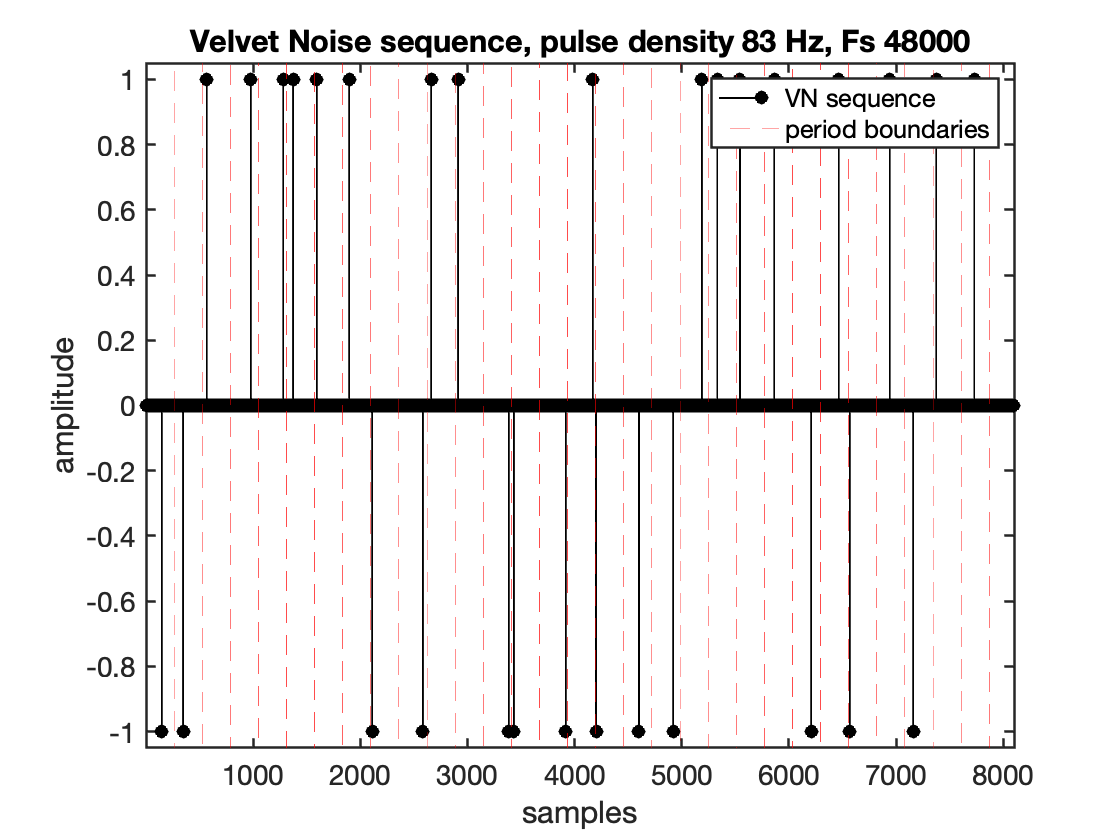

Td = Fs/f;          % pulse period
nPulse = N/Td;      % number of pulses in the sequence

% plot the generated signal
stem(Y, 'k', 'filled', 'LineWidth', 1); hold on;

% plot the segment bounds
segBounds = [1:nPulse] * Td;
for i=1:length(segBounds)
    xline(segBounds(i), '--r', 'LineWidth', 0.5);
end

xlabel('samples')
ylabel('amplitude')
legend('VN sequence', 'period boundaries')
title("Velvet Noise sequence, pulse density " +83+ " Hz, Fs "+Fs)
axis tight
ylim([-1 1]*1.05)

plotSettings(); % set fontsize, linewidth
hold off;

### Plot spectral estimate magnitudes

% mags, mags_norm, freqs

plot_rolloff_pnts = true; % plot rolloff point markers?
nchan = size(mags, 2);    % number of channels available

seghop = 15;
plot_idx = (1:seghop:nchan);   % which channels to plot
nplot = length(plot_idx); % number of channels being plotted

% select which data to plot
% data = mags_rms_shift(:, plot_idx);
data = mags_norm(:,plot_idx);
% data = mags(:,plot_idx);

plt = semilogx(freqs, data, "LineWidth", 1.5);

% generate colors for plot: hue_start, hue_span, num_plots
rgb = genColors(0.3, 0.1, nplot);

% plot cutoff markers
if ~plot_rolloff_pnts
    legend("Location", "SouthWest");
    legend('Position',[0.18 0.2 0.15 0.2]);
else
    hold on;
    rolloff  = -20;  % rolloff to detect, in dB
    min_freq = 750;  % don't search below this frequency
    
    [idxs, rollofffreqs, rolloffvals] = ...
        rolloffIdx(mags_norm(:,plot_idx), rolloff, min_freq, Fs);
    
    % keep track of the plots for legend management
    plts = {}; 
    plts{1} = plt; % add the spectral lines plot (from prev block)
    
    for i = 1:length(idxs)
        plt = semilogx( ...
            freqs(idxs(i)), data(idxs(i), i), ...
            "LineStyle", "none", "Marker", "*");
        plt.Annotation.LegendInformation.IconDisplayStyle = 'off';
        plts{i+1} = plt; % +1: plts{1} is the array of line plots 
    end
    
    % colors
    colororder([rgb; rgb]); % repeated so line and marker colors match
    
    legend([ ...
        plts{1}(1) ... % first of the line plots
        plts{2} ...    % first of the rolloff markers
        ],[ ...
            "segment spectrum" ...
            string(rolloff) + " rolloff point" ...
        ]);
    legend("Location", "West");
    % legend('Position',[0.18 0.2 0.15 0.2]);
    hold off;
end

colororder(rgb);
axis tight;    
xlim([250 20000]);
% ylim([-100 0])
xticks(125*2.^(0:7)) % octaves: 125 > 16000
xlabel('frequency (Hz)')
ylabel('magnitude (dB)')
title(["Normalized spectral magnitude estimates", ...
    "of every "+seghop+" segments"])

plotSettings(); % set fontsize, linewidth
clear nplot plot_idx seghop

### -20dB bandwidth frequency rolloff by window

plot(winStSamps / Fs, rollfreqs, "LineWidth", 1.5);
xlabel('time (s)')
ylabel('frequency')
title(strcat("-20dB bandwidth frequency rolloff, LPC order ", string(lpcOrder)))

plotSettings(); % set fontsize, linewidth

## Individual segments

plot_idxs = 1:2:nSeg;

cnt = 1;
for i = plot_idxs
    subplot(length(plot_idxs), 1, cnt)
    plot(segments{i})
    cnt = cnt+1;
end

## All segments in line

figure();
% include initial silence where the first/early arrivals are
end_idx = seg_bounds(1)-1;
plot((1:end_idx) ./ Fs, zeros(end_idx, 1)); % inital (unsynthesized) part of response
hold on;
for i = 1:nSeg
    st_idx = seg_bounds(i); % seg_bounds is size nSeg+1
    end_idx = st_idx + seg_nsamp(i) - 1;
    plot((st_idx:end_idx) ./ Fs, segments{i});
end
for i = 1:nSeg
    st_idx = seg_bounds(i);
    xline(st_idx / Fs, "--r");
end
hold off;

% generate colors for plot: hue_start, hue_span, num_plots
rgb = genColors(0.3, 0.1, nSeg+1);
% colororder([rgb; rgb]); % for dashed lines colored too
colororder([rgb]);

ylabel('amplitude');
xlabel('time (s)')
title('Pori IR with -20dB bandwidth segment boundaries')
plotSettings(); % set fontsize, linewidth
clear plot_idxs cnt

## Segment divisions

segBoundaries = [segStartIdxs length(X)]; % add the endpoint in for plotting
nBoundaries = length(segBoundaries);

stairs(segBoundaries, nBoundaries:-1:1, 'LineWidth', 2);
yticks([1 nBoundaries])
xticks(round(segStartIdxs(1), -4):10000:round(length(X),-4))
yticklabels(["last" "first"]);
ylabel('segment index')
xlabel('sample index')
ylim([0,nBoundaries+1])
title({"Segment Boundaries", ...
    sprintf("Number of segments: %d", length(segStartIdxs))})

plotSettings(); % set fontsize, linewidth

clear nBoundaries segBoundaries

## Plot whitening filter magnitudes

% semilogx(freqs_lpc, mags_lpc);
plot(freqs_lpc, mags_lpc, 'LineWidth',1.1);

rgb = genColors(0.0, 0.1, nSeg);
colororder(rgb);
% colorbar('Limits',[1 nSeg]); %'Ticks', 1:nSeg); %, 'TickLabels', 1:nSeg)
% colorbar('Ticks', 1:nSeg); %, 'TickLabels', 1:nSeg)
colorbar('TickLabels', 1:2:nSeg)
colormap(rgb)

xlabel('frequency (Hz)')
ylabel('magniutude (dB)')
xticks(1000 * [1, 5, 10, 20])
xticklabels(1000 * [1, 5, 10, 20])
title(["Magnitude response of whitening filters", sprintf("by segment, LP order: %d", lpc_order)])

plotSettings(); % set fontsize, linewidth
axis tight;

## Plot LP magnitudes of whitened segments

% plt = semilogx(freqs_lpc_whitened, mags_lpc_whitened);
plt = plot(freqs_lpc_whitened, mags_lpc_whitened, 'LineWidth',1.5);

rgb = genColors(0.0, 0.1, nSeg);
colororder(rgb);
% colorbar('Limits',[1 nSeg]); %'Ticks', 1:nSeg); %, 'TickLabels', 1:nSeg)
% colorbar('Ticks', 1:nSeg); %, 'TickLabels', 1:nSeg)
colorbar('TickLabels', 1:2:nSeg)
colormap(rgb)


xlabel('frequency (Hz)')
ylabel('magniutude (dB)')
xticks(1000 * [1, 5, 10, 20])
xticklabels(1000 * [1, 5, 10, 20])
title(sprintf("Spectral estimates of whitened segments, LP order: %d", lpc_order))

plotSettings(); % set fontsize, linewidth
axis tight;

### Power of reference segments

plot(reference_gains_norm); hold on;

for i = 1:length(reference_gains_norm)
    plot(i,reference_gains_norm(i), 'o', ...
        'MarkerFaceColor', rgb(i, :), 'MarkerSize', 10);
end
hold off;

rgb = genColors(green, 0.1, nSeg);
colormap(rgb)
title("Signal power of whitened IR segments.")
xlabel("segment index");
ylabel("magnitude (dB)");
xlim([0 nSeg+1])
plotSettings(); % set fontsize, linewidth

### Plot some of the sequences

% plot long analysis segments (1), or IR modeling segments (0)
plotLongSegs = false;

hop = 4; % plot every hop segments
plt_idx = 1:hop:nSeg; % which to plot?
gap = 100; % gap between segment plots
% plt_idx = [1 3 6 nSeg]; % which to plot?
seq = [];
stIdxs = [1];

for i = 1:length(plt_idx)
    this_seq = vn_seq{plt_idx(i)};
%     seq = [seq; this_seq];
    seq = this_seq;
    x = stIdxs(end):stIdxs(end)+length(seq)-1;
    plot(x, seq, ...
        'Color', rgb(plt_idx(i), :), ...
        'LineWidth', 0.8 ...
        ); hold on;
    stIdxs = [stIdxs; stIdxs(end) + length(seq) + gap];
end
hold off;

xticks(stIdxs);
for i = 1:length(stIdxs)
%     xline(stIdxs(i), '-r', 'LineWidth', 2);
end
xticklabels(plt_idx);

title(["Pulse density over time", ("every " +hop+ " segments")])
ylabel('amplitude')
xlabel('segment index')

axis tight

plotSettings(); % set fontsize, linewidth

% clear seq stIdxs plt_idx plotLongSegs

### Plot Power of reference segments with analyzed IR segment power

plot([vn_seq_gains_norm reference_gains_norm], 'LineWidth', 2.5);
% plot([vn_seq_gains reference_gains], 'LineWidth', 2.5);
colororder(["r" "b"]);
title("Signal power of the IR and filtered VN segments.")
xlabel("segment index");
ylabel("magnitude (dB)");

legend(["VN sequences" "IR segments"], "Location", "west")

plotSettings(); % set fontsize, linewidth

### Differential filter gains

filterplot(Bcolor, Acolor, Bdiff, Adiff, Fs, makeup_gains - max(makeup_gains));

plotSettings(); % set fontsize, linewidth

### All-pass Response

An example of the effect of 

a_ap = 0.9;                    % all-pass coefficient
d_ap = [ 225, 341, 441, 556 ]; % all-pass delays
d_aps = "";
for i = 1:length(d_ap)
    d_aps = d_aps + " " +d_ap(i);
end
sig = [1; zeros(49, 1)];

% NOTE: this will determine the length of the returned signal, based on 
% and energy decay tail cutoff point. 
rolloff_threshold = -70;

for del = d_ap
    sig = schrdAllpass(sig, a_ap, del, -35);
end

x = (1:length(sig)) .* 1000 ./ Fs ; % ms
% plot(sig);
% stem(sig);
plot(x, max(mag2db(sig.^2), -100))

ylabel("magnitude (db)");
xlabel("time (ms)")
title("All-pass cascade IR, a = "+a_ap+", M = "+d_aps);

plotSettings(); % set fontsize, linewidth
axis tight
ylim([-100 -25])
xlim([-10 450])

clear sig x Ms a_AP

function plotSettings()
    set(gca, 'FontSize', 14);
    set(gca, 'LineWidth', 1.2);
end